
$$\begin{array}{l}
\frac{\mathrm{dS}}{\mathrm{dt}}=-\beta \mathrm{SA}-\beta \mathrm{SI}-\mathrm{ES}\\
\frac{\mathrm{dA}}{\mathrm{dt}}=\beta \mathrm{SA}+\beta \mathrm{SI}-f_S A-f_R A-{\mathrm{sf}}_T A+\mathrm{ES}\\
\frac{\mathrm{dI}}{\mathrm{dt}}=f_S A-f_R I-f_Q I\\
\frac{\mathrm{dQ}}{\mathrm{dt}}=f_Q I+{\mathrm{sf}}_T A-f_R Q\\
\frac{\mathrm{dR}}{\mathrm{dt}}=f_R \left(Q+I+A\right)
\end{array}$$


close all;
fR = 1/14;
Ss = 0.6

Ss =    0.600000000000000


fS = (0.6).*fR;
s = 0.9;
fQ = 0.3;
fT = 1./(2/7);
beta = 0.2;
E = 10;
clc;
format long;
%step 1: define the equations
f = @(t, y) [-beta.*y(1).*y(2)-beta.*y(1).*y(3)-y(1).*E; beta.*y(1).*y(2)+beta.*y(1).*y(3)-y(2).*fR-y(2).*fS-y(2).*s.*fT+y(1).*E; y(2).*fS-y(3).*fQ-fR.*y(3); fQ.*y(3)+y(2).*s.*fS-y(4).*fR; fR.*(y(4)+y(3)+y(2))];
[x,y] = explicit_euler(f,[0,100],[1000;0;0;0;0],0.1) % Calling Euler function

x =                    0   0.100000000000000   0.200000000000000   0.300000000000000   0.400000000000000   0.500000000000000   0.600000000000000   0.700000000000000   0.800000000000000   0.900000000000000   1.000000000000000   1.100000000000000   1.200000000000000   1.300000000000000   1.400000000000000   1.500000000000000   1.600000000000000   1.700000000000000   1.800000000000000   1.900000000000001   2.000000000000000   2.100000000000001   2.200000000000001   2.300000000000001   2.400000000000001   2.500000000000001   2.600000000000001   2.700000000000001   2.800000000000001   2.900000000000001   3.000000000000001   3.100000000000001   3.200000000000002   3.300000000000002   3.400000000000002   3.500000000000002   3.600000000000002   3.700000000000002   3.800000000000002   3.900000000000002   4.000000000000002   4.100000000000001   4.200000000000001   4.300000000000001   4.400000000000000   4.500000000000000   4.600000000000000   4.699999999999999   4.799999999999999   4.89999999999

y = 	1.0e+03 *

   1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0    

x =                    0   0.100000000000000   0.200000000000000   0.300000000000000   0.400000000000000   0.500000000000000   0.600000000000000   0.700000000000000   0.800000000000000   0.900000000000000   1.000000000000000   1.100000000000000   1.200000000000000   1.300000000000000   1.400000000000000   1.500000000000000   1.600000000000000   1.700000000000000   1.800000000000000   1.900000000000001   2.000000000000000   2.100000000000001   2.200000000000001   2.300000000000001   2.400000000000001   2.500000000000001   2.600000000000001   2.700000000000001   2.800000000000001   2.900000000000001   3.000000000000001   3.100000000000001   3.200000000000002   3.300000000000002   3.400000000000002   3.500000000000002   3.600000000000002   3.700000000000002   3.800000000000002   3.900000000000002   4.000000000000002   4.100000000000001   4.200000000000001   4.300000000000001   4.400000000000000   4.500000000000000   4.600000000000000   4.699999999999999   4.799999999999999   4.89999999999

y = 	1.0e+03 *

   1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0    

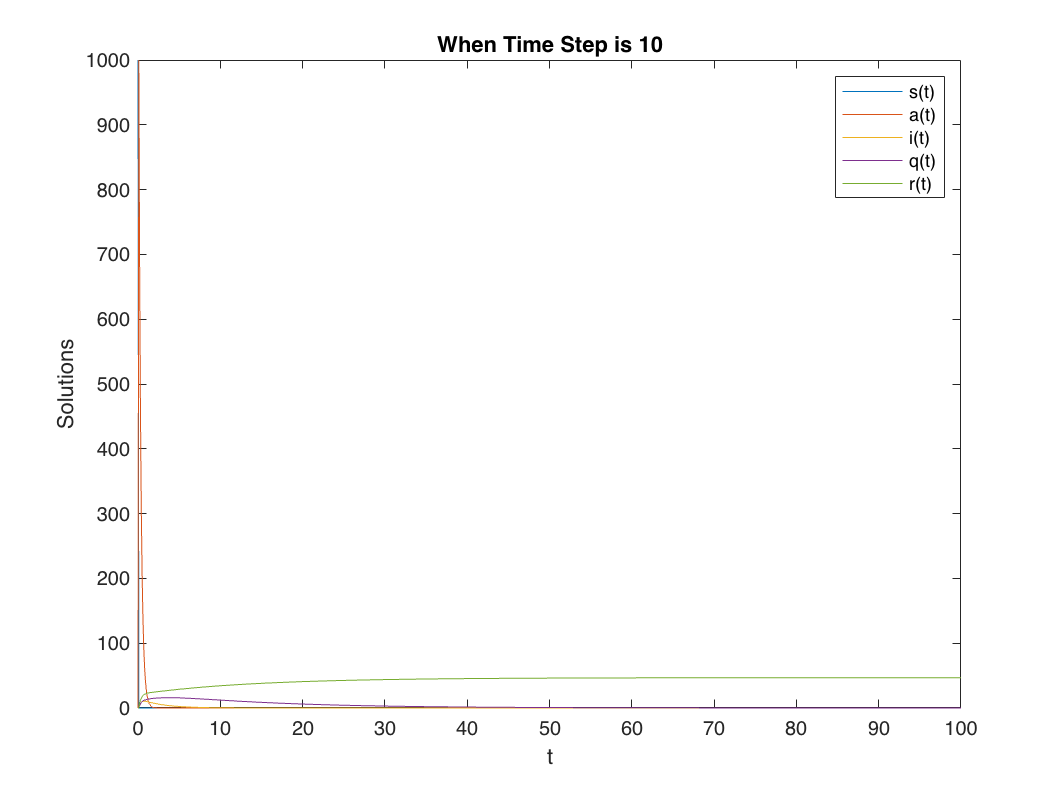

plot(x,y);
title('When Time Step is 10');
legend('s(t)', 'a(t)', 'i(t)', 'q(t)', 'r(t)')
xlabel('t')
ylabel('Solutions')

display(y)

y = 	1.0e+03 *

   1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0    


N = 10000;
E = 4;
TR = 14;
Reff=.3;


f = @(x) ((N.*E.*TR)./(1-Reff)).*(1./(1+Ss+s.*fT.*TR));
F = @(x) (Ss+s.*fT.*TR).*(f(x)./TR);
x_1 = 0:0.01:2.5

x_1 =                    0   0.010000000000000   0.020000000000000   0.030000000000000   0.040000000000000   0.050000000000000   0.060000000000000   0.070000000000000   0.080000000000000   0.090000000000000   0.100000000000000   0.110000000000000   0.120000000000000   0.130000000000000   0.140000000000000   0.150000000000000   0.160000000000000   0.170000000000000   0.180000000000000   0.190000000000000   0.200000000000000   0.210000000000000   0.220000000000000   0.230000000000000   0.240000000000000   0.250000000000000   0.260000000000000   0.270000000000000   0.280000000000000   0.290000000000000   0.300000000000000   0.310000000000000   0.320000000000000   0.330000000000000   0.340000000000000   0.350000000000000   0.360000000000000   0.370000000000000   0.380000000000000   0.390000000000000   0.400000000000000   0.410000000000000   0.420000000000000   0.430000000000000   0.440000000000000   0.450000000000000   0.460000000000000   0.470000000000000   0.480000000000000   0.490000000

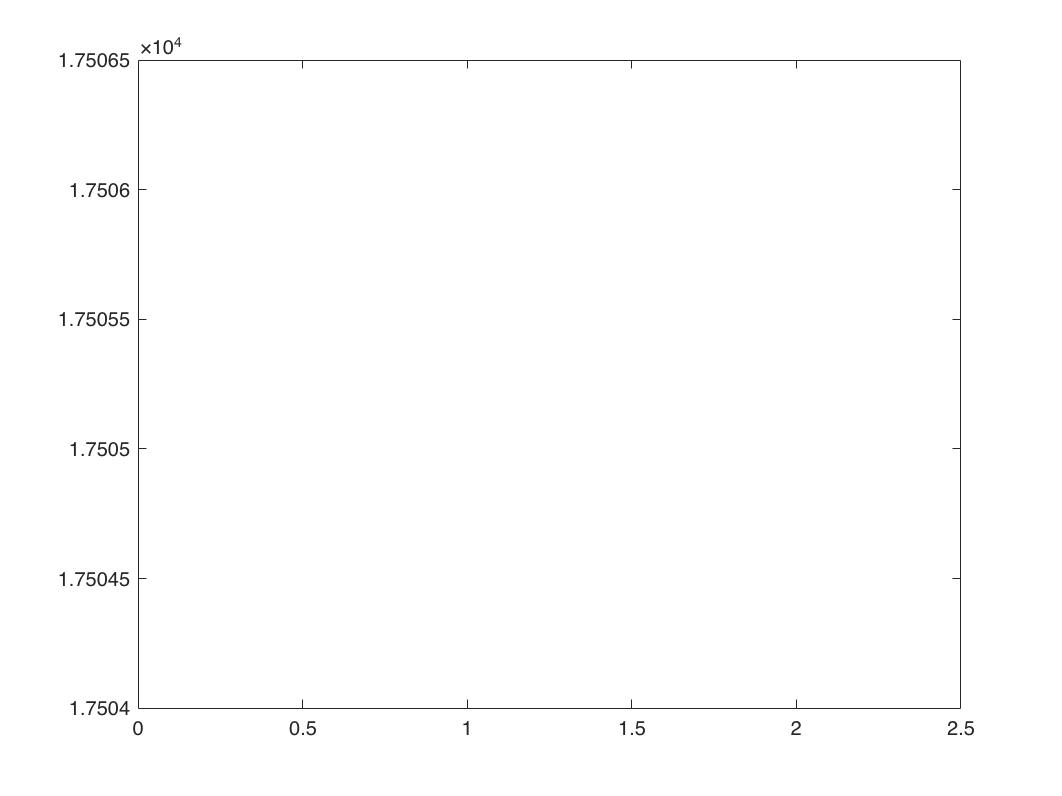

plot(x_1, f(x_1))

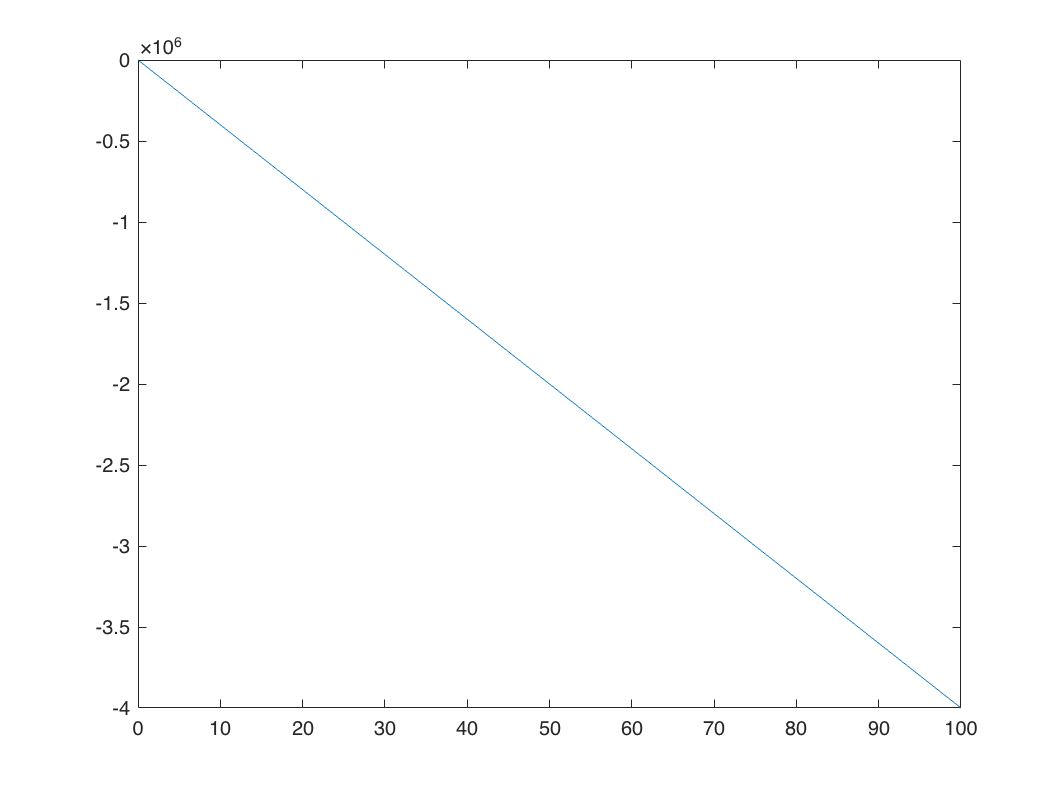


Reff = 2;

W = @(x) ((N.*E.*TR)./(1-Reff)).*(x./TR);
x2 = 0:0.1:100;
plot(x2, W(x2))

function [x, y] = explicit_euler( f, xRange, y_initial, h )
% This function uses Euler’s explicit method to solve the ODE
% dv/dt=f(t,v); x refers to independent and y refers to dependent variables
% f defines the differential equation of the problem
% xRange = [x1, x2] where the solution is sought on
% y_initial = column vector of initial values for y at x1
% numSteps = number of equally-sized steps to take from x1 to x2
% x = row vector of values of x
% y = matrix whose k-th column is the approximate solution at x(k)
    x(1) = xRange(1);
    numSteps = ( xRange(2) - xRange(1) ) /h ;
    y(:,1) = y_initial(:);
    for k = 1 : numSteps
        x(k+1) = x(k) + h;
        y(:,k+1) = y(:,k) + h * f( x(k), y(:,k) );
    end
    display(x)
    display(y)
end

Next